# Control and Instrumentation Lab Assignment 6

**SWARNENDU PAUL 19EE3FP18**

## Bode and Nyquist plots

**Question 1.**

**i.**

Given, $G(s)=\frac{100(s+2)}{s(s+5)(s+10)}$ Hence closed loop transfer function will be,


$$\frac{G(s)}{1+G(s)}=\frac{100(s+2)}{s(s+5)(s+10)+100(s+2)}$$
 

Transfer function:

tf1=tf([100,200],[1,15,150,200])

tf1 =
 
         100 s + 200
  --------------------------
  s^3 + 15 s^2 + 150 s + 200
 
Continuous-time transfer function.



**a)** Bode plot:-

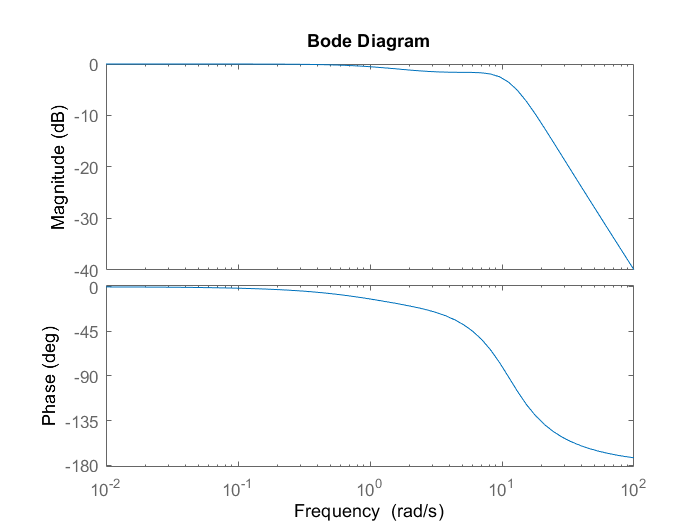

bode(tf1,{0.01,100})

**b)** Gain margin, Phase margin, Phase crossover frequency, Gain crossover frequency:-

allmargin(tf1) 

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


**c)** resonant peak, resonance frequency and bandwidth:-

[gpeak,fpeak]=getPeakGain(tf1) %#ok<*ASGLU> 

gpeak = 1

fpeak = 0

bw=bandwidth(tf1) %#ok<*NASGU> 

bw = 10.4767

**ii. **

Given, $G(s)=\frac{20(s+1)}{s(s+5)(s^2+2s+10)}$ hence, closed loop transfer function will be,


$$\frac{G(s)}{1+G(s)}=\frac{20(s+1)}{s(s+5)(s^2+2s+10)+20(s+1)}$$
 

Transfer function:

tf2=tf([20,20],[1,7,20,70,20])

tf2 =
 
             20 s + 20
  --------------------------------
  s^4 + 7 s^3 + 20 s^2 + 70 s + 20
 
Continuous-time transfer function.



**a)** Bode plot:-

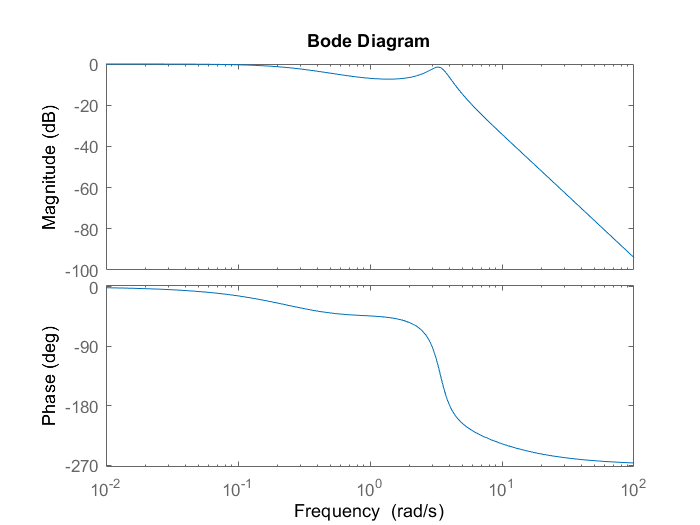

bode(tf2,{0.01,100})

**b)** Gain margin, Phase margin, Phase crossover frequency, Gain crossover frequency:-

allmargin(tf2)

ans = struct with fields:
     GainMargin: 2.1393
    GMFrequency: 4.0142
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


**c)** resonant peak, resonance frequency and bandwidth:-

[gpeak,fpeak]=getPeakGain(tf2)

gpeak = 1.0000

fpeak = 0

bw=bandwidth(tf2)

bw = 0.3508

**iii.**

Given, $G(s)=\frac{10(s^2+0.4s+1)}{s(s^2+0.8s+9)}$ hence, closed loop transfer function will be,


$$\frac{G(s)}{1+G(s)}=\frac{10(s^2+0.4s+1)}{s(s^2+0.8s+9)+10(s^2+0.4s+1)}$$
 

Transfer function:

tf3=tf([10,4,10],[1,10.8,13,10])

tf3 =
 
      10 s^2 + 4 s + 10
  --------------------------
  s^3 + 10.8 s^2 + 13 s + 10
 
Continuous-time transfer function.



**a)** Bode plot:-

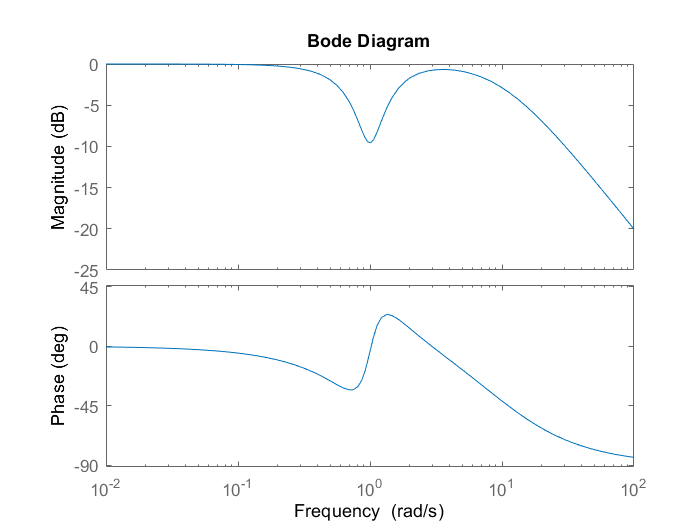

bode(tf3,{0.01,100})

**b)** Gain margin, Phase margin, Phase crossover frequency, Gain crossover frequency:-

allmargin(tf3)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


**c)** resonant peak, resonance frequency and bandwidth:-

[gpeak,fpeak]=getPeakGain(tf3)

gpeak = 1

fpeak = 0

bw=bandwidth(tf3)

bw = 0.5943

**Question 2.**

Given, open loop $G(s)=\frac{K}{s(s+1)(s+5)}$ hence, closed loop transfer function will be,


$$\frac{G(s)}{1+G(s)}=\frac{K}{s(s+1)(s+5)+K}$$
 

Transfer functions for K = 10,20 and 100

H1=tf(10,[1,6,5,10])

H1 =
 
            10
  ----------------------
  s^3 + 6 s^2 + 5 s + 10
 
Continuous-time transfer function.



H2=tf(20,[1,6,5,20])

H2 =
 
            20
  ----------------------
  s^3 + 6 s^2 + 5 s + 20
 
Continuous-time transfer function.



H3=tf(100,[1,6,5,100])

H3 =
 
            100
  -----------------------
  s^3 + 6 s^2 + 5 s + 100
 
Continuous-time transfer function.



**a)** Bode plot of closed loop systems:-

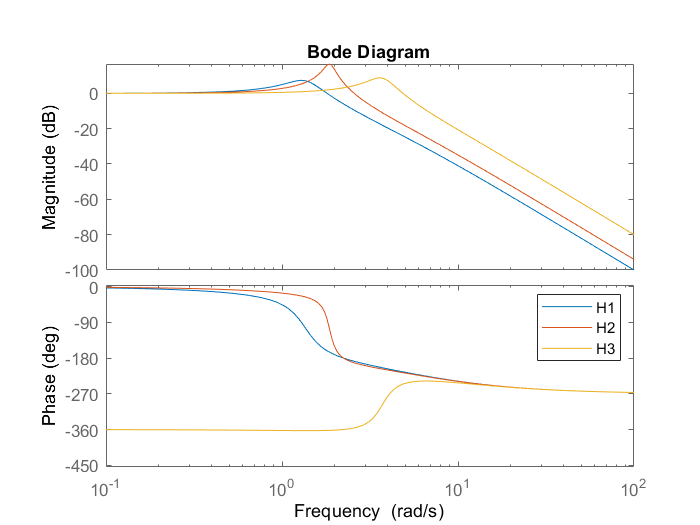

bode(H1,H2,H3)
legend

all three plots above are frequency response of closed loop system. 

**b)** We cannot predict the stability from the frequency response/bode plot of the closed loop system. As we cannot replace s by $j\omega$ in case of K=100 as it is an unstable system which has region of convergence $Re(s)\geq a$ where $a>0$. 

Hence we find the gain and phase margin of the open loop system for 3 values of K,

H1=tf(10,[1,6,5,0]);
H2=tf(20,[1,6,5,0]);
H3=tf(100,[1,6,5,0]);
fprintf("For H1(K=10):")

For H1(K=10):

allmargin(H1)

ans = struct with fields:
     GainMargin: 3
    GMFrequency: 2.2361
    PhaseMargin: 25.3898
    PMFrequency: 1.2271
    DelayMargin: 0.3611
    DMFrequency: 1.2271
         Stable: 1


fprintf("For H2(K=20):")

For H2(K=20):

allmargin(H2)

ans = struct with fields:
     GainMargin: 1.5000
    GMFrequency: 2.2361
    PhaseMargin: 8.9095
    PMFrequency: 1.8147
    DelayMargin: 0.0857
    DMFrequency: 1.8147
         Stable: 1


fprintf("For H3(K=100):")

For H3(K=100):

allmargin(H3)

ans = struct with fields:
     GainMargin: 0.3000
    GMFrequency: 2.2361
    PhaseMargin: -23.6504
    PMFrequency: 3.9073
    DelayMargin: 1.5024
    DMFrequency: 3.9073
         Stable: 0


As we can see, gain and phase margin for K=10,20 is positive and also for those values of K the  closed loop system is stable. But for K=100, both gain and phase margins are negative, so the closed loop system is unstable.

**c)**  We have to find the minimum value of K for which the system becomes unstable, i.e. the gain margin becomes equal to 0dB and phase margin becomes equal to $0^\circ$. 

At phase crossover, imaginary part of the open loop expression should be 0 when we put $j\omega$ in place of s. S0, $\omega^3=5\omega$ and hence, at limiting point, $\omega_{cg}=\omega_{cp}=\sqrt{5}$ 

and $\frac{K}{-6\omega^2}=-1$ as gain margin is also 0dB. So minimum value of K for which the system is unstable is **K=30**

k=29.9;
H=tf(k,[1,6,5,0]);
allmargin(H)

ans = struct with fields:
     GainMargin: 1.0033
    GMFrequency: 2.2361
    PhaseMargin: 0.0713
    PMFrequency: 2.2323
    DelayMargin: 5.5762e-04
    DMFrequency: 2.2323
         Stable: 1


k=30;
H=tf(k,[1,6,5,0]);
allmargin(H)

ans = struct with fields:
     GainMargin: 1.0000
    GMFrequency: 2.2361
    PhaseMargin: 9.5374e-06
    PMFrequency: 2.2361
    DelayMargin: 7.4443e-08
    DMFrequency: 2.2361
         Stable: 0


As we observe from the above data, after K=30 the system has ~0 gain and phase margin and same crossover frequencies and closed loop system becomes unstable.

At K=30 the closed loop system is marginally stable.

**d) **putting $j\omega$ in place of s in the open loop expression we get,


$$G(j\omega)=\frac{K}{-6\omega^2+j(5\omega-\omega^3)}$$
 

phase margin = $\frac{\pi}{6}$ , Hence, $tan(\pi+\frac{\pi}{6})=\frac{5-\omega^2}{6\omega}$ 

So gain crossover frequency is given by the equation, 


$$\omega_{cg}^2+2\sqrt{3}\omega_{cg}-5=0$$
 
$$\therefore \omega_{cg} = 2\sqrt2 -\sqrt3=1.0964$$
 

Also the gain is equal to 1 at $\omega=\omega_{cg}$ so $K=|-6\omega^2+j(5\omega-\omega^3)| = 8.32798$

From previous calculation we know, $\omega_{cp}=\sqrt5$ so at $\omega=\omega_{cp}$, 

Gain margin = $\frac{6\omega^2}{K}=\frac{30}{8.32798}=3.6023$

Hence Gain margin = 11.1316dB

k=8.32798;
H=tf(k,[1,6,5,0]);
allmargin(H)

ans = struct with fields:
     GainMargin: 3.6023
    GMFrequency: 2.2361
    PhaseMargin: 30.0000
    PMFrequency: 1.0964
    DelayMargin: 0.4776
    DMFrequency: 1.0964
         Stable: 1


We can verify the above calculation from this data. 